cd /Users/serg/github_projects/QASS_SVM/data
rng('default')
rng(1234)

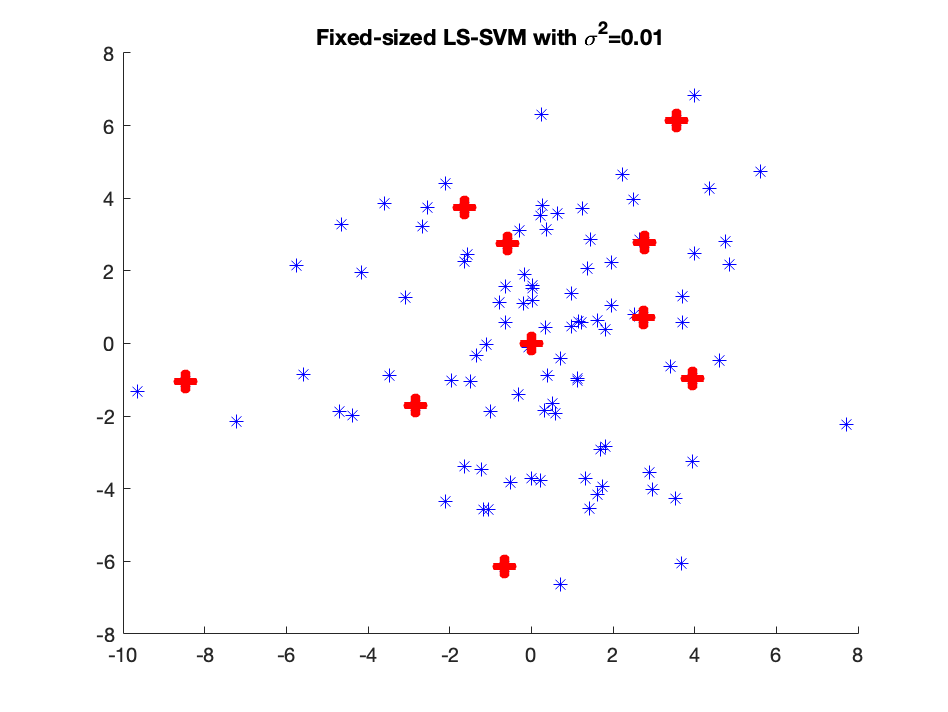

X = 3.*randn(100,2);
ssize = 10;
subset = zeros(ssize,2);
sig2 = 0.01;

for t = 1:100,

  %
  % new candidate subset
  %
  r = ceil(rand*ssize);
  candidate = [subset([1:r-1 r+1:end],:); X(t,:)];
  
  %
  % is this candidate better than the previous?
  %
  if kentropy(candidate, 'RBF_kernel',sig2)>...
        kentropy(subset, 'RBF_kernel',sig2),
    subset = candidate;
  end
end

figure;
hold on;
plot(X(:,1),X(:,2),'b*'); 
plot(subset(:,1),subset(:,2),'ro','linewidth',6); 
title('Fixed-sized LS-SVM with \sigma^2=0.01');
hold off; 
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_33_1.png','Resolution',300);

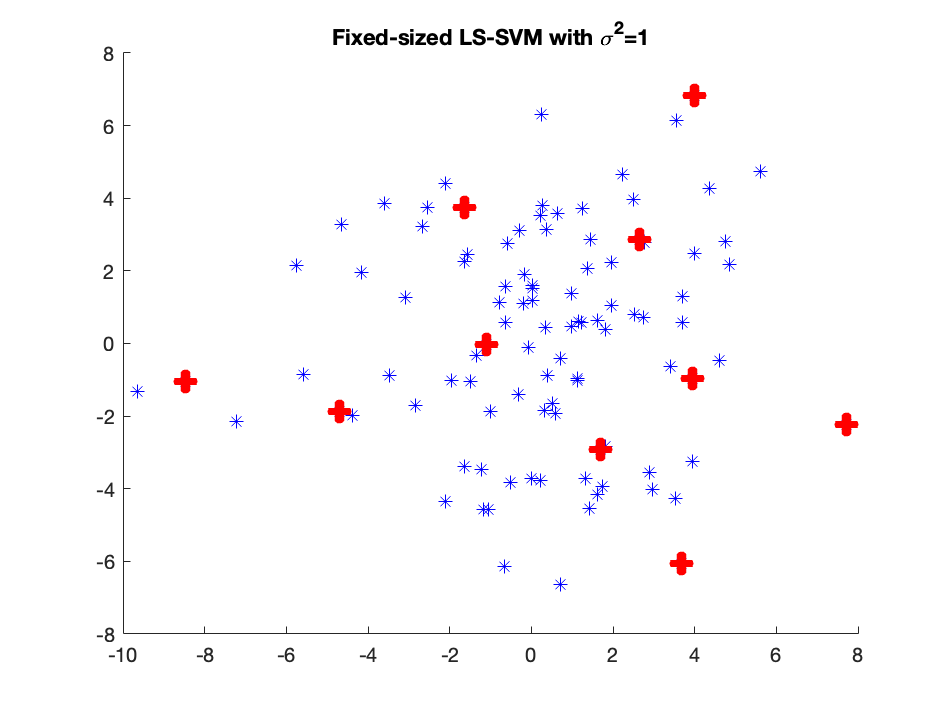

sig2 = 1;
subset = zeros(ssize,2);
for t = 1:100,

  %
  % new candidate subset
  %
  r = ceil(rand*ssize);
  candidate = [subset([1:r-1 r+1:end],:); X(t,:)];
  
  %
  % is this candidate better than the previous?
  %
  if kentropy(candidate, 'RBF_kernel',sig2)>...
        kentropy(subset, 'RBF_kernel',sig2),
    subset = candidate;
  end
end

figure;
hold on;
plot(X(:,1),X(:,2),'b*'); 
plot(subset(:,1),subset(:,2),'ro','linewidth',6); 
title('Fixed-sized LS-SVM with \sigma^2=1');
hold off; 
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_33_2.png','Resolution',300);

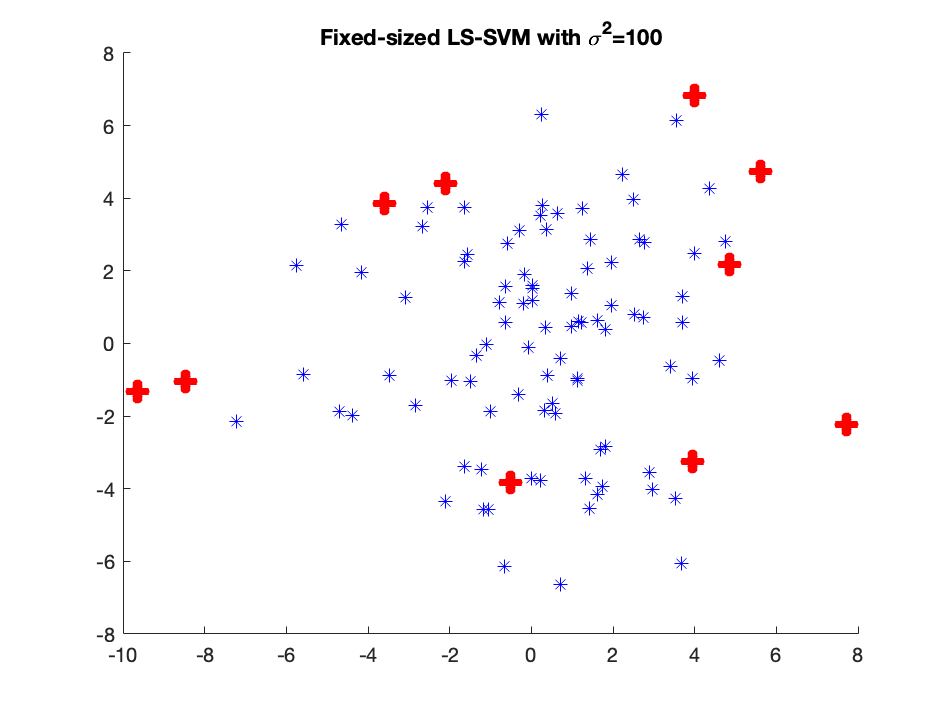

sig2 = 100;
subset = zeros(ssize,2);

for t = 1:100,

  %
  % new candidate subset
  %
  r = ceil(rand*ssize);
  candidate = [subset([1:r-1 r+1:end],:); X(t,:)];
  
  %
  % is this candidate better than the previous?
  %
  if kentropy(candidate, 'RBF_kernel',sig2)>...
        kentropy(subset, 'RBF_kernel',sig2),
    subset = candidate;
  end
end

figure;
hold on;
plot(X(:,1),X(:,2),'b*'); 
plot(subset(:,1),subset(:,2),'ro','linewidth',6); 
title('Fixed-sized LS-SVM with \sigma^2=100');
hold off; 
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_33_3.png','Resolution',300);